IBranchContent = "P(Y) + D"

IBranchContent = "P(Y) + D"

QBranchContent = "C/A + D"

QBranchContent = "C/A + D"

ShowVisualizations =  true;
WriteWaveformToFile = false;
PRNID = 1;
% Set this value to 1 to generate the waveform from the first bit of the
% navigation data
NavDataBitStartIndex = 1321;

% Set this value to control the number of navigation data bits in the
% generated waveform
NumNavDataBits = 2;
cnavConfig = HelperGPSNavigationConfig(SignalType = "CNAV", PRNID = PRNID)

cnavConfig =   HelperGPSNavigationConfig with properties:

                           SignalType: "CNAV"
                                PRNID: 1
                         MessageTypes: [4×15 double]
                               HOWTOW: 1
                           L2CPhasing: 0
                         SignalHealth: [3×1 double]
                           WeekNumber: 2149
               GroupDelayDifferential: 0
                 ReferenceTimeOfClock: 0
                  SemiMajorAxisLength: 26560000
            ChangeRateInSemiMajorAxis: 0
                 MeanMotionDifference: 0
           RateOfMeanMotionDifference: 0
                         Eccentricity: 0.0200
                          MeanAnomaly: 0
             ReferenceTimeOfEphemeris: 0
              HarmonicCorrectionTerms: [6×1 double]
                  IntegrityStatusFlag: 0
                    ArgumentOfPerigee: -0.5200
                 Rat

lnavConfig = HelperGPSNavigationConfig(SignalType = "LNAV", PRNID = PRNID)

lnavConfig =   HelperGPSNavigationConfig with properties:

                       SignalType: "LNAV"
                            PRNID: 1
                     FrameIndices: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25]
                       TLMMessage: 0
                           HOWTOW: 1
                    AntiSpoofFlag: 0
                        CodesOnL2: "P-code"
                      L2PDataFlag: 0
                         SVHealth: 0
                 IssueOfDataClock: 0
                            URAID: 0
                       WeekNumber: 2149
           GroupDelayDifferential: 0
    SVClockCorrectionCoefficients: [3×1 double]
             ReferenceTimeOfClock: 0
              SemiMajorAxisLength: 26560000
             MeanMotionDifference: 0
                  FitIntervalFlag: 0
                     Eccentricity: 0.0200
                      MeanAnomaly: 0
         Refere

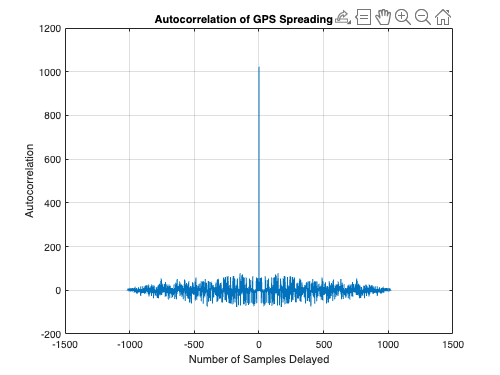

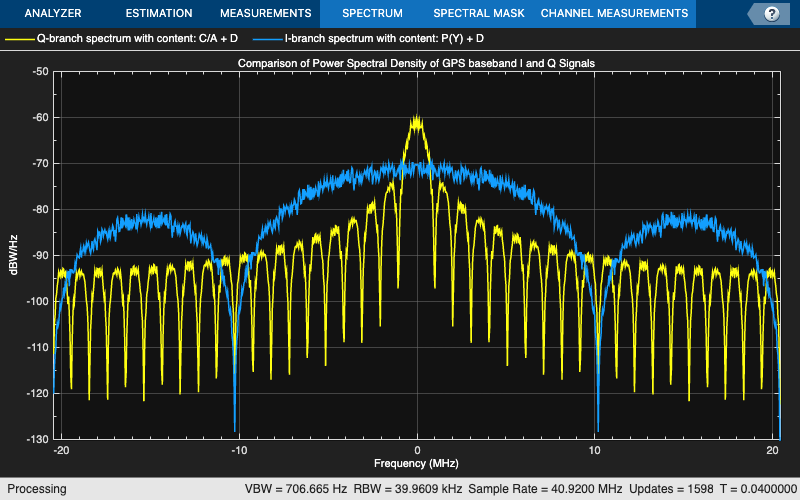

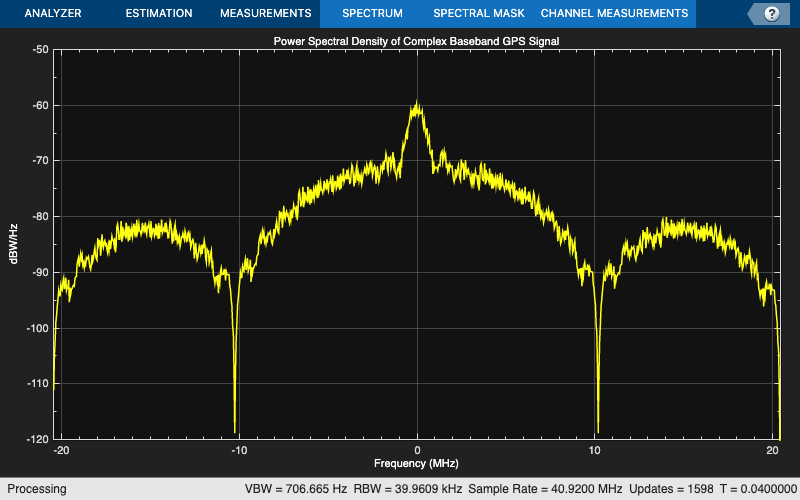


cnavData = HelperGPSNAVDataEncode(cnavConfig);
% Initialize the trellis for convolutional encoder
trellis = poly2trellis(7,["1+x+x^2+x^3+x^6" "1+x^2+x^3+x^5+x^6"]);
cenc = comm.ConvolutionalEncoder(TrellisStructure = trellis, ...
    TerminationMethod = "Continuous");
encodedCNAVData = cenc(cnavData);

lnavData = HelperGPSNAVDataEncode(lnavConfig);

CLCodeResetIdx = 75; % CL-code spans over 75 data bits before resetting
numBBSamplesPerDataBit = 204600;
CLCodeIdx = mod(NavDataBitStartIndex-1,CLCodeResetIdx);
IQContent = [IBranchContent,QBranchContent];
pgen = gpsPCode(PRNID = PRNID, InitialTime = ...
    lnavConfig.ReferenceTimeOfEphemeris, ...
    OutputCodeLength = numBBSamplesPerDataBit);
% Pre-initialize the baseband waveform for speed
gpsBBWaveform = zeros(numBBSamplesPerDataBit*NumNavDataBits,1);

if WriteWaveformToFile == 1
    bbWriter = comm.BasebandFileWriter("Waveform.bb",10.23e6,0);
end

for iDataBit = 1:NumNavDataBits
    dataBitIdx = iDataBit+NavDataBitStartIndex-1;
    bbSamplesIndices = ((iDataBit-1)*numBBSamplesPerDataBit+1): ...
        (iDataBit*numBBSamplesPerDataBit);
    gpsBBWaveform(bbSamplesIndices) = HelperGPSBasebandWaveform(IQContent,pgen,PRNID, ...
        CLCodeIdx,lnavData(dataBitIdx),encodedCNAVData(dataBitIdx));
    CLCodeIdx = mod(CLCodeIdx+1,CLCodeResetIdx);
    if WriteWaveformToFile == 1
        bbWriter(gpsBBWaveform(bbSamplesIndices));
    end
end

if WriteWaveformToFile == 1
    release(bbWriter);
end

if ShowVisualizations
      % Because P-code is 10 times faster than C/A-code or L2 CM-/L2 CL-code,
    % initialise down sample factor to 10
    downsampleFactor = 10;
    IBranchData = real(gpsBBWaveform);
    QBranchData = imag(gpsBBWaveform(1:downsampleFactor:end));
    lags = (-1023:1023).';
    plot(lags,xcorr(real(QBranchData(1:1023)),1023))
    grid on
    xlabel("Number of Samples Delayed")
    ylabel("Autocorrelation")
    title("Autocorrelation of GPS Spreading Code")
      repeatFactor = 40;
    % Repeat the generated BPSK signal of C/A-code to see the adjacent bands spectrum
    QBranchUpsampled = repmat(QBranchData(:).',repeatFactor,1);
    QBranchUpsampled = QBranchUpsampled(:);
    % Repeat the generated BPSK signal of in-phase component to see the
    % adjacent bands spectrum. Repeat the in-phase branch samples ten times less
    % as every sample in quadrature-branch corresponds to 10 samples in in-phase branch
    IBranchUpsampled = repmat(IBranchData(:).',repeatFactor/10,1);
    IBranchUpsampled = real(IBranchUpsampled(:));
    iqScope = spectrumAnalyzer(SampleRate = 1.023e6*repeatFactor, ...
        SpectrumType = "Power density", ...
        SpectrumUnits = "dBW", ...
        YLimits = [-130, -50], Title = ...
        "Comparison of Power Spectral Density of GPS baseband I and Q Signals", ...
        ShowLegend = true, ChannelNames = ...
        ["Q-branch spectrum with content: " + QBranchContent, ...
        "I-branch spectrum with content: " + IBranchContent]);

    iqScope([QBranchUpsampled,IBranchUpsampled]);
      repeatFactor = 4;
    % Repeat the generated BPSK signal to see the adjacent bands spectrum
    updata = repmat(gpsBBWaveform(:).',repeatFactor,1);
    updata = updata(:);
    bbscope = spectrumAnalyzer(SampleRate = 10*1.023e6*repeatFactor, ...
        SpectrumType = "Power density", ...
        SpectrumUnits = "dBW", ...
        YLimits = [-120,-50], ...
        Title = "Power Spectral Density of Complex Baseband GPS Signal");
    bbscope(updata);
end